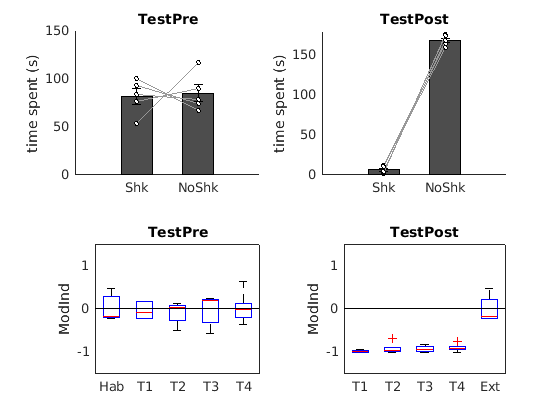

%% Look at effect of conditionning
figure
clear ZoneTimeH
Files=PathForExperimentsEmbReact('Habituation_EyeShock');
for mm=1:length(Files.path)
    cd(Files.path{mm}{1})
    load('behavResources_SB.mat')
    for k=1:5
        Behav.ZoneEpoch{k}=Behav.ZoneEpoch{k};
        ZoneTimeH(mm,k)=sum(Stop(Behav.ZoneEpoch{k},'s')-Start(Behav.ZoneEpoch{k},'s'));%./sum(sum(Zone{k}));
    end
end
ShckSide=ZoneTimeH(:,1:5:end)+ZoneTimeH(:,4:5:end);
NoShckSide=ZoneTimeH(:,2:5:end)+ZoneTimeH(:,5:5:end);
ModExploH=[[(ShckSide-NoShckSide)./(ShckSide+NoShckSide)]];


clear ZoneTime
Files=PathForExperimentsEmbReact('TestPre_EyeShock');
for mm=1:length(Files.path)
    for c=1:4
        cd(Files.path{mm}{c})
        load('behavResources_SB.mat')
        for k=1:5
            Behav.ZoneEpoch{k}=Behav.ZoneEpoch{k};
            ZoneTime{c}(mm,k)=sum(Stop(Behav.ZoneEpoch{k},'s')-Start(Behav.ZoneEpoch{k},'s'));%./sum(sum(Zone{k}));
        end
    end
end

AllDat=[];
for c=1:4
    AllDat=[AllDat;(ZoneTime{c}(:,:)')];
end
subplot(221)
PlotErrorBarN([mean(AllDat(1:5:end,:)+AllDat(4:5:end,:));mean(AllDat(2:5:end,:)+AllDat(5:5:end,:))]',0,1);
ShckSide=AllDat(1:5:end,:)+AllDat(4:5:end,:);
NoShckSide=AllDat(2:5:end,:)+AllDat(5:5:end,:);
ModExplo=[(ShckSide-NoShckSide)./(ShckSide+NoShckSide)]';
title('TestPre'), ylabel('time spent (s)')
set(gca,'XTick',[1:2],'XTickLabel',{'Shk','NoShk'})

subplot(223)
[i1,j1] = ndgrid(1:size(ModExplo,1),1:size(ModExplo,2));
[i2,j2] = ndgrid(1:size(ModExploH,1),(1:size(ModExploH,2))+size(ModExplo,2));
z = accumarray([i1(:),j1(:);i2(:),j2(:)],[ModExploH(:);ModExplo(:)]);
z(z==0)=NaN;
boxplot(z), hold on
set(gca,'XTick',[1:5],'XTickLabel',{'Hab','T1','T2','T3','T4'})
,ylabel('ModInd'),line(xlim,[0 0],'color','k')
title('TestPre')
ylim([-1.5 1.5])


clear ZoneTimeH
Files=PathForExperimentsEmbReact('Extinction_EyeShock');
for mm=1:length(Files.path)
    cd(Files.path{mm}{1})
    load('behavResources_SB.mat')
    for k=1:5
        Behav.ZoneEpoch{k}=Behav.ZoneEpoch{k};
        ZoneTimeH(mm,k)=sum(Stop(Behav.ZoneEpoch{k},'s')-Start(Behav.ZoneEpoch{k},'s'));%./sum(sum(Zone{k}));
    end
end
ShckSide=ZoneTimeH(:,1:5:end)+ZoneTimeH(:,4:5:end);
NoShckSide=ZoneTimeH(:,2:5:end)+ZoneTimeH(:,5:5:end);

clear ZoneTime
Files=PathForExperimentsEmbReact('TestPost_EyeShock');
for mm=1:length(Files.path)
    for c=1:4
        cd(Files.path{mm}{c})
        load('behavResources_SB.mat')
        for k=1:5
            Behav.ZoneEpoch{k}=Behav.ZoneEpoch{k};
            ZoneTime{c}(mm,k)=sum(Stop(Behav.ZoneEpoch{k},'s')-Start(Behav.ZoneEpoch{k},'s'));%./sum(sum(Zone{k}));
        end
    end
end
AllDat=[];
for c=1:4
    AllDat=[AllDat;(ZoneTime{c}(:,1:5)')];
end
subplot(222)
PlotErrorBarN([mean(AllDat(1:5:end,:)+AllDat(4:5:end,:));mean(AllDat(2:5:end,:)+AllDat(5:5:end,:))]',0,1);
title('TestPost')
set(gca,'XTick',[1:2],'XTickLabel',{'Shk','NoShk'})
ylabel('time spent (s)')
ylim([0 180])

ShckSide=AllDat(1:5:end,:)+AllDat(4:5:end,:);
NoShckSide=AllDat(2:5:end,:)+AllDat(5:5:end,:);
ModExplo=[(ShckSide-NoShckSide)./(ShckSide+NoShckSide)]';
subplot(224)
[i1,j1] = ndgrid(1:size(ModExplo,1),1:size(ModExplo,2));
[i2,j2] = ndgrid(1:size(ModExploH,1),(1:size(ModExploH,2))+size(ModExplo,2));
z = accumarray([i1(:),j1(:);i2(:),j2(:)],[ModExplo(:);ModExploH(:)]);
z(z==0)=NaN;

boxplot(z), hold on
set(gca,'XTick',[1:5],'XTickLabel',{'T1','T2','T3','T4','Ext'})
,ylabel('ModInd'),line(xlim,[0 0],'color','k')
ylim([-1.5 1.5])
title('TestPost')

Now we'll have a look at the behaviour when the animal is blocked

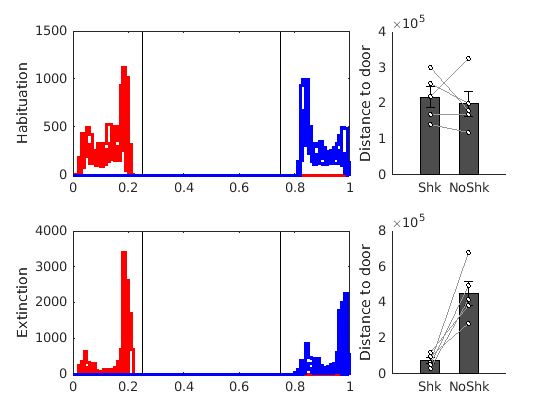

clear MeanDist Dist
figure
subplot(2,3,1:2)
Files=PathForExperimentsEmbReact('HabituationBlockedShock_EyeShock');
MouseToAvoid=[560]; % mice with noisy data to exclude
Files=RemoveElementsFromDir(Files,'nmouse',MouseToAvoid);
for mm=1:length(Files.path)
    cd(Files.path{mm}{1})
    load('behavResources_SB.mat')
    Dist.Shock{mm}=Data(Behav.LinearDist);
    MeanDist.Shock(mm)=sum(Data(Behav.LinearDist)-Params.DoorPos(1)).^2;
    [Y,X]=hist(Dist.Shock{mm},[0:0.01:1]);
    stairs(X,Y,'r','linewidth',3), hold on
end
Files=PathForExperimentsEmbReact('HabituationBlockedSafe_EyeShock');
MouseToAvoid=[560]; % mice with noisy data to exclude
Files=RemoveElementsFromDir(Files,'nmouse',MouseToAvoid);
for mm=1:length(Files.path)
    cd(Files.path{mm}{1})
    load('behavResources_SB.mat')
    Dist.Safe{mm}=Data(Behav.LinearDist);
    MeanDist.Safe(mm)=sum(Data(Behav.LinearDist)-Params.DoorPos(2)).^2;
    [Y,X]=hist(Dist.Safe{mm},[0:0.01:1]);
    stairs(X,Y,'b','linewidth',3)
end
line([0.25 0.25],ylim,'color','k')
line([0.75 0.75],ylim,'color','k')
ylabel('Habituation')
subplot(2,3,3)
bar(2,nanmean(MeanDist.Safe),'FaceColor',[0.6 0.6 1]), hold on
bar(1,nanmean(MeanDist.Shock),'FaceColor',[1 0.6 0.6])
plotSpread({MeanDist.Shock;MeanDist.Safe},'distributionColors',[ 0 0 0;0 0 0])
set(gca,'XTick',[1,2],'XTickLabel',{'Shk','NoShk'})
ylabel('Distance to door')

clear MeanDist Dist
subplot(2,3,4:5)
Files=PathForExperimentsEmbReact('ExtinctionBlockedShock_EyeShock');
MouseToAvoid=[560]; % mice with noisy data to exclude
Files=RemoveElementsFromDir(Files,'nmouse',MouseToAvoid);
for mm=1:length(Files.path)
    cd(Files.path{mm}{1})
    load('behavResources_SB.mat')
    Dist.Shock{mm}=Data(Behav.LinearDist);
    MeanDist.Shock(mm)=sum(Data(Behav.LinearDist)-Params.DoorPos(1)).^2;
    [Y,X]=hist(Dist.Shock{mm},[0:0.01:1]);
    stairs(X,Y,'r','linewidth',3), hold on
end
Files=PathForExperimentsEmbReact('ExtinctionBlockedSafe_EyeShock');
MouseToAvoid=[560]; % mice with noisy data to exclude
Files=RemoveElementsFromDir(Files,'nmouse',MouseToAvoid);
for mm=1:length(Files.path)
    cd(Files.path{mm}{1})
    load('behavResources_SB.mat')
    Dist.Safe{mm}=Data(Behav.LinearDist);
    MeanDist.Safe(mm)=sum(Data(Behav.LinearDist)-Params.DoorPos(2)).^2;
    [Y,X]=hist(Dist.Safe{mm},[0:0.01:1]);
    stairs(X,Y,'b','linewidth',3)
end
line([0.25 0.25],ylim,'color','k')
line([0.75 0.75],ylim,'color','k')
ylabel('Extinction')
subplot(2,3,6)
bar(2,nanmean(MeanDist.Safe),'FaceColor',[0.6 0.6 1]), hold on
bar(1,nanmean(MeanDist.Shock),'FaceColor',[1 0.6 0.6])
plotSpread({MeanDist.Shock;MeanDist.Safe},'distributionColors',[ 0 0 0;0 0 0])
set(gca,'XTick',[1,2],'XTickLabel',{'Shk','NoShk'})
ylabel('Distance to door')
set(gca,'XTick',[1,2],'XTickLabel',{'Shk','NoShk'})
ylabel('Distance to door')

Look at what's happening during conditionning

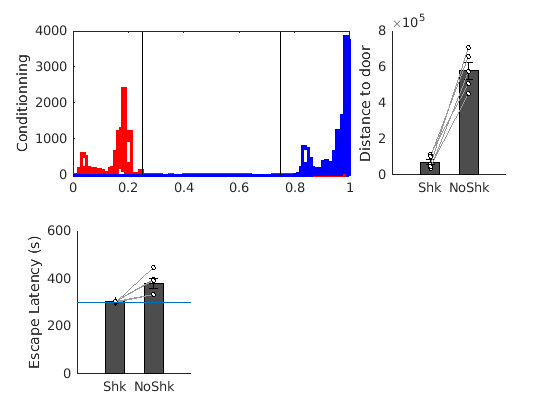

% Position when the door is closed and latency to escape
clear MeanDist Dist EscapeLat
DoorClosedEpoch=intervalSet(0,300*1e4);
figure
subplot(2,3,1:2)
Files=PathForExperimentsEmbReact('UMazeCondBlockedShock_EyeShock');
MouseToAvoid=[560]; % mice with noisy data to exclude
Files=RemoveElementsFromDir(Files,'nmouse',MouseToAvoid);
for mm=1:length(Files.path)
    for c=1:3
        cd(Files.path{mm}{c})
        load('behavResources_SB.mat')
        Dist.Shock{mm,c}=Data(Restrict(Behav.LinearDist,DoorClosedEpoch));
        MeanDist.Shock(mm,c)=sum(Data(Restrict(Behav.LinearDist,DoorClosedEpoch))-Params.DoorPos(1)).^2;
        if not(isempty(min(Start(Behav.ZoneEpoch{3},'s'))))
            EscapeLat.Shock(mm,c)=min(Start(Behav.ZoneEpoch{3},'s'));
        else
            EscapeLat.Shock(mm,c)=500;
        end
        [Y,X]=hist(Dist.Shock{mm},[0:0.01:1]);
        stairs(X,Y,'r','linewidth',3), hold on
    end
end
Files=PathForExperimentsEmbReact('UMazeCondBlockedSafe_EyeShock');
MouseToAvoid=[560]; % mice with noisy data to exclude
Files=RemoveElementsFromDir(Files,'nmouse',MouseToAvoid);
for mm=1:length(Files.path)
    for c=1:3
        cd(Files.path{mm}{c})
        load('behavResources_SB.mat')
        Dist.Safe{mm,c}=Data(Restrict(Behav.LinearDist,DoorClosedEpoch));
        MeanDist.Safe(mm,c)=sum(Data(Restrict(Behav.LinearDist,DoorClosedEpoch))-Params.DoorPos(2)).^2;
        if not(isempty(min(Start(Behav.ZoneEpoch{3},'s'))))
            EscapeLat.Safe(mm,c)=min(Start(Behav.ZoneEpoch{3},'s'));
        else
            EscapeLat.Safe(mm,c)=500;
        end
        [Y,X]=hist(Dist.Safe{mm,c},[0:0.01:1]);
        stairs(X,Y,'b','linewidth',3)
    end
end
line([0.25 0.25],ylim,'color','k')
line([0.75 0.75],ylim,'color','k')
ylabel('Conditionning')
subplot(2,3,3)
PlotErrorBarN([mean(MeanDist.Shock');mean(MeanDist.Safe')]',0);
set(gca,'XTick',[1,2],'XTickLabel',{'Shk','NoShk'})
ylabel('Distance to door')
subplot(2,3,4)
PlotErrorBarN([mean(EscapeLat.Shock');mean(EscapeLat.Safe')]',0);
set(gca,'XTick',[1,2],'XTickLabel',{'Shk','NoShk'})
ylabel('Escape Latency (s)')
line(xlim,[300 300])

Now lets see where and how much the are freezing

clear all
SessionNames={'UMazeCond_EyeShock' 'UMazeCondBlockedShock_EyeShock' 'UMazeCondBlockedSafe_EyeShock' };
for ss=1:length(SessionNames)
    Files=PathForExperimentsEmbReact(SessionNames{ss});
    MouseToAvoid=[560]; % mice with noisy data to exclude
    Files=RemoveElementsFromDir(Files,'nmouse',MouseToAvoid);
    for mm=1:length(Files.path)
        for c=1:3
            cd(Files.path{mm}{c})
            load('behavResources_SB.mat')
            dt=median(diff(Range(Behav.Vtsd,'s')));
            if not(isempty(Behav.FreezeAccEpoch))
                FreezeEpoch=Behav.FreezeAccEpoch;
            else
                FreezeEpoch=Behav.FreezeEpoch;
            end
            FreezeDur=length(Data(Restrict(Behav.Vtsd,FreezeEpoch)));
            SessDur=length(Data(Behav.Vtsd));
            for k=1:5
                tempTot=length(Data(Restrict(Behav.Vtsd,Behav.ZoneEpoch{k})));
                tempFreeze=length(Data(Restrict(Behav.Vtsd,and(Behav.ZoneEpoch{k},FreezeEpoch))));
                TempPercFzTotLoc(c,k)=tempFreeze./tempTot;
                TempPercFzTotFz(c,k)=tempFreeze./FreezeDur;
                TempPerOccup(c,k)=tempTot./SessDur;
                TempFreezingTime(c,k)=tempFreeze*dt;
            end
        end
        for k=1:5
            PercFzTotLoc.(strtok(SessionNames{ss},'_'))(mm,k)=nanmean(TempPercFzTotLoc(:,k));
            PercFzTotFz.(strtok(SessionNames{ss},'_'))(mm,k)=nanmean(TempPercFzTotFz(:,k));
            PerOccup.(strtok(SessionNames{ss},'_'))(mm,k)=nanmean(TempPerOccup(:,k));
            FreezingTime.(strtok(SessionNames{ss},'_'))(mm,k)=nansum(TempFreezingTime(:,k));
        end
    end
end


figure
%PlotErrorBarN([FreezingTime.ExtinctionBlockedShock(:,1),FreezingTime.ExtinctionBlockedSafe(:,2)],0);
bar(1,nanmean(nanmean(FreezingTime.UMazeCond(:,2)+FreezingTime.UMazeCondBlockedSafe(:,2)')),'FaceColor',[0.6 0.6 1]), hold on
bar(2,nanmean(nanmean(FreezingTime.UMazeCond(:,1)+FreezingTime.UMazeCondBlockedShock(:,1)')),'FaceColor',[1 0.6 0.6]), hold on
plotSpread({nanmean(FreezingTime.UMazeCond(:,2)+FreezingTime.UMazeCondBlockedSafe(:,2)');nanmean(FreezingTime.UMazeCond(:,1)+FreezingTime.UMazeCondBlockedShock(:,1)')},'distributionColors',[ 0 0 0;0 0 0])
set(gca,'XTick',[1,2],'XTickLabel',{'Safe','Shock'})
box off

figure
TotFzTime=FreezingTime.UMazeCondBlockedSafe+FreezingTime.UMazeCondBlockedShock+FreezingTime.UMazeCond;

Undefined variable "FreezingTime" or class "FreezingTime.UMazeCondBlockedSafe".

TotFzTime=TotFzTime(:,[1,4,2,5,3]);
PlotErrorBarN(TotFzTime,0);
set(gca,'XTick',[1:5],'XTickLabel',{'Shk','ShkCntr','NoShk','NoShkCent','Cent'})
title('AllSessions'), ylabel('tot time freezing (s)')
figure
subplot(3,1,1)
TotFzTime=FreezingTime.UMazeCond;
TotFzTime=TotFzTime(:,[1,4,2,5,3]);
PlotErrorBarN(TotFzTime,0)
subplot(3,1,1)
TotFzTime=FreezingTime.UMazeCond;
TotFzTime=TotFzTime(:,[1,4,2,5,3]);
PlotErrorBarN(TotFzTime,0);
set(gca,'XTick',[1:5],'XTickLabel',{'Shk','ShkCntr','NoShk','NoShkCent','Cent'})
title('Free Explo')
subplot(3,1,2)
TotFzTime=FreezingTime.UMazeCondBlockedSafe;
TotFzTime=TotFzTime(:,[1,4,2,5,3]);
PlotErrorBarN(TotFzTime,0);
set(gca,'XTick',[1:5],'XTickLabel',{'Shk','ShkCntr','NoShk','NoShkCent','Cent'})
title('Blocked Safe side'), ylabel('tot time freezing (s)')
subplot(3,1,3)
TotFzTime=FreezingTime.UMazeCondBlockedShock;
TotFzTime=TotFzTime(:,[1,4,2,5,3]);
PlotErrorBarN(TotFzTime,0);
set(gca,'XTick',[1:5],'XTickLabel',{'Shk','ShkCntr','NoShk','NoShkCent','Cent'})
title('Blocked Shock side')

How much freezing during the post test session

clear all
SessionNames={'ExtinctionBlockedShock_EyeShock' 'ExtinctionBlockedSafe_EyeShock' };

for ss=1:length(SessionNames)
    Files=PathForExperimentsEmbReact(SessionNames{ss});
    MouseToAvoid=[560]; % mice with noisy data to exclude
    Files=RemoveElementsFromDir(Files,'nmouse',MouseToAvoid);
    for mm=1:length(Files.path)
        for c=1
            cd(Files.path{mm}{c})
            load('behavResources_SB.mat')
            dt=median(diff(Range(Behav.Vtsd,'s')));
            if not(isempty(Behav.FreezeAccEpoch))
                FreezeEpoch=Behav.FreezeAccEpoch;
            else
                FreezeEpoch=Behav.FreezeEpoch;
            end
            FreezeDur=length(Data(Restrict(Behav.Vtsd,FreezeEpoch)));
            SessDur=length(Data(Behav.Vtsd));
            for k=1:5
                tempTot=length(Data(Restrict(Behav.Vtsd,Behav.ZoneEpoch{k})));
                tempFreeze=length(Data(Restrict(Behav.Vtsd,and(Behav.ZoneEpoch{k},FreezeEpoch))));
                TempPercFzTotLoc(c,k)=tempFreeze./tempTot;
                TempPercFzTotFz(c,k)=tempFreeze./FreezeDur;
                TempPerOccup(c,k)=tempTot./SessDur;
                TempFreezingTime(c,k)=tempFreeze*dt;
            end
        end
        for k=1:5
            PercFzTotLoc.(strtok(SessionNames{ss},'_'))(mm,k)=nanmean(TempPercFzTotLoc(:,k));
            PercFzTotFz.(strtok(SessionNames{ss},'_'))(mm,k)=nanmean(TempPercFzTotFz(:,k));
            PerOccup.(strtok(SessionNames{ss},'_'))(mm,k)=nanmean(TempPerOccup(:,k));
            FreezingTime.(strtok(SessionNames{ss},'_'))(mm,k)=nansum(TempFreezingTime(:,k));
        end
    end
end


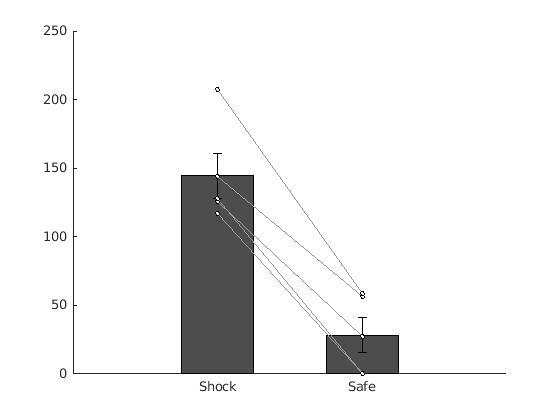

figure
%PlotErrorBarN([FreezingTime.ExtinctionBlockedShock(:,1),FreezingTime.ExtinctionBlockedSafe(:,2)],0);
bar(1,nanmean(FreezingTime.ExtinctionBlockedSafe(:,2)'),'FaceColor',[0.6 0.6 1]), hold on
bar(2,nanmean(FreezingTime.ExtinctionBlockedShock(:,1)'),'FaceColor',[1 0.6 0.6])
plotSpread({FreezingTime.ExtinctionBlockedSafe(:,2);FreezingTime.ExtinctionBlockedShock(:,1)},'distributionColors',[ 0 0 0;0 0 0],'MarkerSize',10)

set(gca,'XTick',[1,2],'XTickLabel',{'Shock','Safe'})

Look at risk assesmment behaviour

clear ZoneTime
Files=PathForExperimentsEmbReact('TestPre_EyeShock');
tps=[0:0.01:4];
for mm=1:length(Files.path)
    RiskAsess.TestPre.ToSafeMov{mm}=[];RiskAsess.TestPre.ToSafeType{mm}=[];
    RiskAsess.TestPre.ToShockMov{mm}=[];RiskAsess.TestPre.ToShockType{mm}=[];
    for c=1:4
        cd(Files.path{mm}{c})
        clear Behav
        load('behavResources_SB.mat')
        for type=1:3
            RiskAsess.TestPre.ToSafe{type}(mm,c)=sum(Behav.RAUser.ToSafe>=type-1);
            RiskAsess.TestPre.ToShock{type}(mm,c)=sum(Behav.RAUser.ToShock>=type-1);
        end
        % Shock
        if not(isempty(Start(Behav.RAEpoch.ToShock)))
            SmooDiffLinDist=tsd(Range(Behav.LinearDist),[0;diff(runmean(Data(Behav.LinearDist),20))]);
            tpsout=FindClosestZeroCross(Start(Behav.RAEpoch.ToShock),SmooDiffLinDist,1);
            for t=1:length(tpsout)
                try
                    LitEp=intervalSet(tpsout(t)-2*1e4,tpsout(t)+2*1e4);
                    dattemp=interp1(Range(Restrict(SmooDiffLinDist,LitEp))-(tpsout(t)-2*1e4),Data(Restrict(SmooDiffLinDist,LitEp)),[0:0.01:4]*1e4);
                    RiskAsess.TestPre.ToShockMov{mm}=[RiskAsess.TestPre.ToShockMov{mm};dattemp];
                    RiskAsess.TestPre.ToShockType{mm}=[RiskAsess.TestPre.ToShockType{mm},Behav.RAUser.ToShock(t)];   
                end
            end
        end
        
        % Safe
        if not(isempty(Start(Behav.RAEpoch.ToSafe)))
            SmooDiffLinDist=tsd(Range(Behav.LinearDist),[0;diff(runmean(Data(Behav.LinearDist),20))]);
            tpsout=FindClosestZeroCross(Start(Behav.RAEpoch.ToSafe),SmooDiffLinDist,-1);
            for t=1:length(tpsout)
                try
                    LitEp=intervalSet(tpsout(t)-2*1e4,tpsout(t)+2*1e4);
                    dattemp=interp1(Range(Restrict(SmooDiffLinDist,LitEp))-(tpsout(t)-2*1e4),Data(Restrict(SmooDiffLinDist,LitEp)),[0:0.01:4]*1e4);
                    RiskAsess.TestPre.ToSafeMov{mm}=[ RiskAsess.TestPre.ToSafeMov{mm};dattemp];
                    RiskAsess.TestPre.ToSafeType{mm}=[RiskAsess.TestPre.ToSafeType{mm},Behav.RAUser.ToSafe(t)];
                end
            end
        end
    end
end

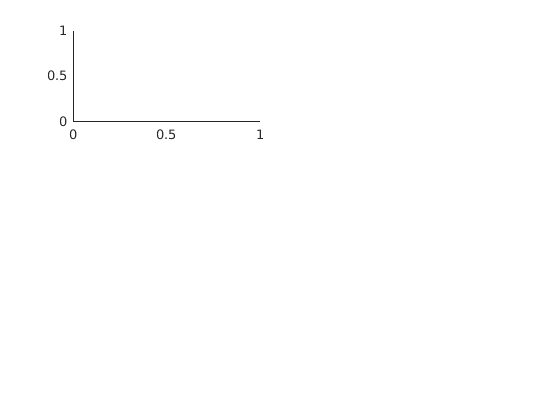

Reference to non-existent field 'TestPre'.


clear ZoneTime
Files=PathForExperimentsEmbReact('TestPost_EyeShock');
for mm=1:length(Files.path)
    for c=1:4
        cd(Files.path{mm}{c})
        clear Behav
        load('behavResources_SB.mat')
        for k=1:5
            for type=1:3
                RiskAsess.TestPost.ToSafe{type}(mm,c)=sum(Behav.RAUser.ToSafe>=type-1);
                RiskAsess.TestPost.ToShock{type}(mm,c)=sum(Behav.RAUser.ToShock>=type-1);
            end
        end
    end
end

clear ZoneTime
Files=PathForExperimentsEmbReact('UMazeCond_EyeShock');
MouseToAvoid=[560,117,431]; % mice with noisy data to exclude
Files=RemoveElementsFromDir(Files,'nmouse',MouseToAvoid);
for mm=1:length(Files.path)
    for c=1:3
        cd(Files.path{mm}{c})
        clear Behav
        load('behavResources_SB.mat')
        for k=1:5
            for type=1:3
                RiskAsess.UMAzeCond.ToSafe{type}(mm,c)=sum(Behav.RAUser.ToSafe>=type-1);
                RiskAsess.UMAzeCond.ToShock{type}(mm,c)=sum(Behav.RAUser.ToShock>=type-1);
            end
        end
    end
end

clear ZoneTime
Files=PathForExperimentsEmbReact('UMazeCondBlockedShock_EyeShock');
MouseToAvoid=[560,117,431]; % mice with noisy data to exclude
Files=RemoveElementsFromDir(Files,'nmouse',MouseToAvoid);
for mm=1:length(Files.path)
    for c=1:3
        cd(Files.path{mm}{c})
        clear Behav
        load('behavResources_SB.mat')
        for k=1:5
            for type=1:3
                RiskAsess.UMAzeCondBlockedShock.ToSafe{type}(mm,c)=sum(Behav.RAUser.ToSafe>=type-1);
                RiskAsess.UMAzeCondBlockedShock.ToShock{type}(mm,c)=sum(Behav.RAUser.ToShock>=type-1);
            end
        end
    end
end

clear ZoneTime
Files=PathForExperimentsEmbReact('UMazeCondBlockedSafe_EyeShock');
MouseToAvoid=[560,117,431]; % mice with noisy data to exclude
Files=RemoveElementsFromDir(Files,'nmouse',MouseToAvoid);
for mm=1:length(Files.path)
    for c=1:3
        cd(Files.path{mm}{c})
        clear Behav
        load('behavResources_SB.mat')
        for k=1:5
            for type=1:3
                RiskAsess.UMAzeCondBlockedSafe.ToSafe{type}(mm,c)=sum(Behav.RAUser.ToSafe>=type-1);
                RiskAsess.UMAzeCondBlockedSafe.ToShock{type}(mm,c)=sum(Behav.RAUser.ToShock>=type-1);
            end
        end
    end
end

figure
DurSess=3;
for type=1:3
    subplot(3,2,(type-1)*2+1)
    PlotErrorBarN([mean(RiskAsess.TestPre.ToShock{type}')/DurSess;mean(RiskAsess.TestPre.ToSafe{type}')/DurSess]',0,1);
    set(gca,'XTick',[1,2],'XTickLabel',{'To Shock','To Safe'})
    xlabel('RA/min')
    if type==1
        title('Test Pre')
    end
    subplot(3,2,(type-1)*2+2)
    PlotErrorBarN([mean(RiskAsess.TestPost.ToShock{type}')/DurSess;mean(RiskAsess.TestPost.ToSafe{type}')/DurSess]',0,1);
    set(gca,'XTick',[1,2],'XTickLabel',{'To Shock','To Safe'})
    if type==1
        title('Test Post')
    end
end



figure
DurSess=8;
for type=1:3
    subplot(3,3,(type-1)*3+1)
    PlotErrorBarN([mean(RiskAsess.UMAzeCond.ToShock{type}')/DurSess;mean(RiskAsess.UMAzeCond.ToSafe{type}')/DurSess]',0,1);
    set(gca,'XTick',[1,2],'XTickLabel',{'To Shock','To Safe'})
    xlabel('RA/min')
    if type==1
        title('UMazeCond')
    end
end

DurSess=3;
for type=1:3
    subplot(3,3,(type-1)*3+2)
    PlotErrorBarN([mean(RiskAsess.UMAzeCondBlockedShock.ToShock{type}')/DurSess;mean(RiskAsess.UMAzeCond.ToSafe{type}')/DurSess]',0,1);
    set(gca,'XTick',[1,2],'XTickLabel',{'To Shock','To Safe'})
    xlabel('RA/min')
    if type==1
        title('UMAzeCondBlockedShock')
    end
end

DurSess=3;
for type=1:3
    subplot(3,3,(type-1)*3+3)
    PlotErrorBarN([mean(RiskAsess.UMAzeCondBlockedSafe.ToShock{type}')/DurSess;mean(RiskAsess.UMAzeCond.ToSafe{type}')/DurSess]',0,1);
    set(gca,'XTick',[1,2],'XTickLabel',{'To Shock','To Safe'})
    xlabel('RA/min')
    if type==1
        title('UMAzeCondBlockedSafe')
    end
end

